# Presentación Final (Cinemática Diferencial de Piernas)

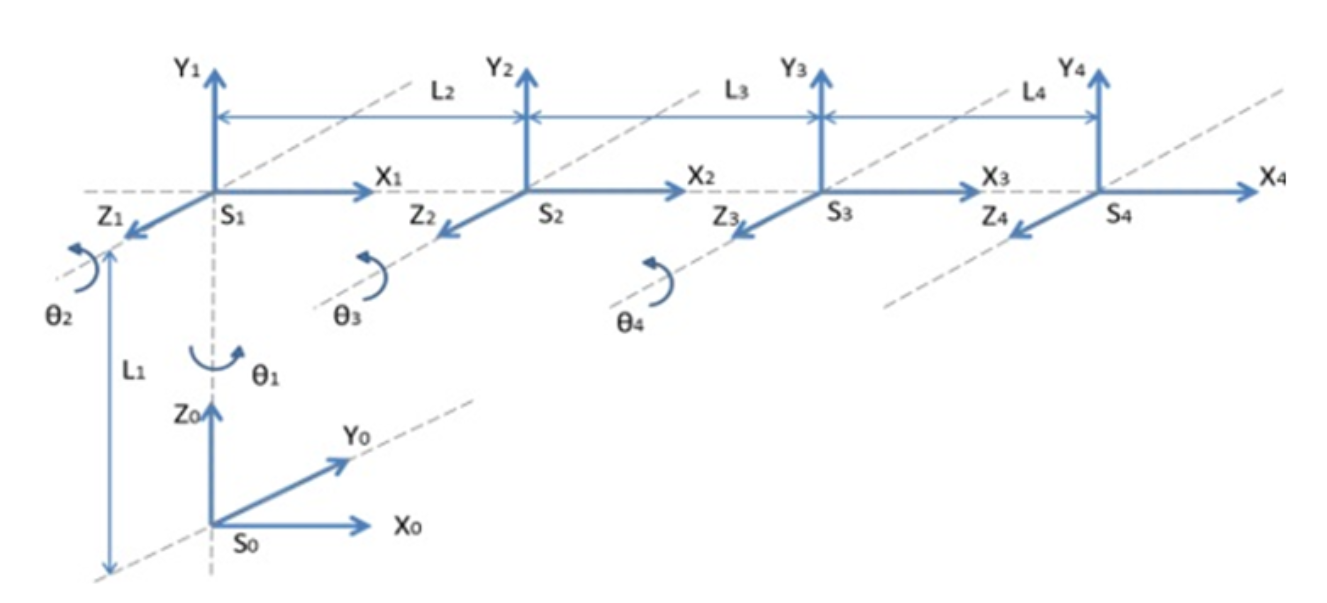

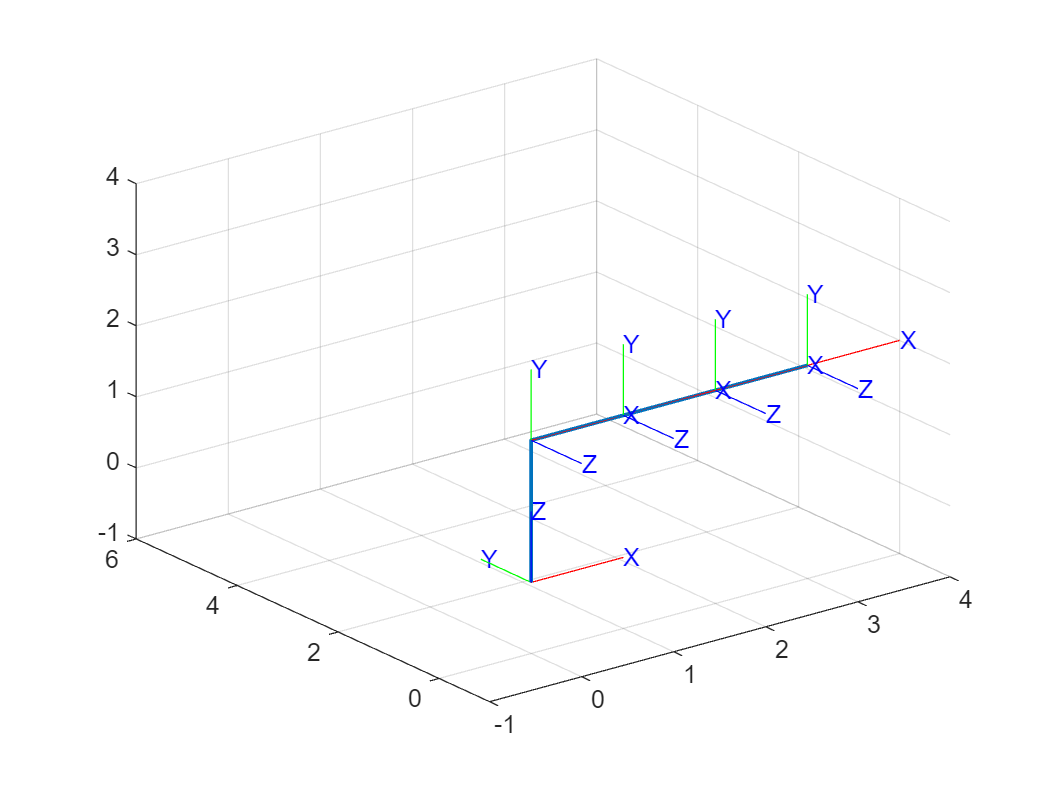

%Limpieza de pantalla
clear all
close all
clc

%Calculamos las matrices de transformación homogénea
H0=SE3;
H1=SE3(rotx(pi/2), [0 0 2]);
H2=SE3(roty(0), [1 0 0]);
H3=SE3(roty(0), [1 0 0]);
H4=SE3(roty(0), [1 0 0]);

H20 = H1*H2;
H30 = H20*H3;
H40 = H30*H4;
 

%Coordenadas de la estructura de translación y rotación
x=[0 0 1 2 3 ];
y=[0 0 0 0 0 ];
z=[0 2 2 2 2 ];

plot3(x, y, z,'LineWidth', 1.5); axis([-1 4 -1 6 -1 4]); grid on;
hold on;

%Graficamos la trama absoluta o global 
trplot(H0,'rgb','axis', [-1 4 -1 6 -1 4])
% 
% %Realizamos una animación para la siguiente trama
 %pause;
  tranimate(H0, H1,'rgb','axis', [-1 4 -1 6 -1 2])
% %Realizamos una animación para la siguiente trama
 %pause;
 tranimate(H1, H20,'rgb','axis', [-1 4 -1 6 -1 2])
% % %Realizamos una animación para la siguiente trama
 %pause;
  tranimate(H20, H30,'rgb','axis', [-1 4 -1 6 -1 2])
% % %Realizamos una animación para la siguiente trama
 %pause;
  tranimate(H30, H40,'rgb','axis', [-1 4 -1 6 -1 2])

hold off

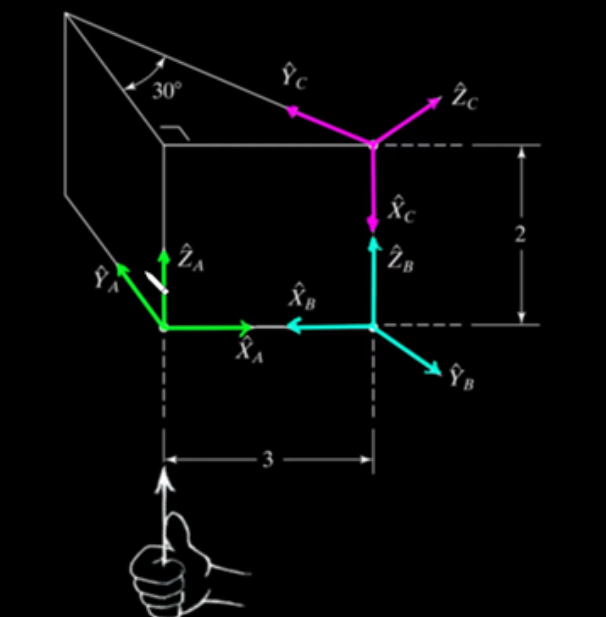

%Calculamos las matrices de transformación homogénea
H0=SE3;
H1=SE3(rotz(pi), [3 0 0]);
H2=SE3(roty(pi/2), [0 0 0]);
H3=SE3(rotx(150*pi/180), [-2 0 0]);

H20= H1*H2;
H30= H20*H3; %Matriz de transformación homogenea global de 3 a 0 

%Coordenadas de la estructura de translación y rotación
x=[0 3 3 0 0 0     0     0 0     3];
y=[0 0 0 0 0 5.196 5.196 0 5.196 0];
z=[0 0 2 2 0 0     2     2 2     2];

plot3(x, y, z,'LineWidth', 1.5); axis([-1 4 -1 6 -1 2]); grid on;
hold on;

%Graficamos la trama absoluta o global 
trplot(H0,'rgb','axis', [-1 4 -1 6 -1 2])
% 
% %Realizamos una animación para la siguiente trama

  tranimate(H0, H1,'rgb','axis', [-1 4 -1 6 -1 2])
% %Realizamos una animación para la siguiente trama

 tranimate(H1, H20,'rgb','axis', [-1 4 -1 6 -1 2])
% % %Realizamos una animación para la siguiente trama

  tranimate(H20, H30,'rgb','axis', [-1 4 -1 6 -1 2])
  disp(H30);

     0      -0.5     0.866         3
     0     0.866       0.5         0
    -1         0         0         2
     0         0         0         1


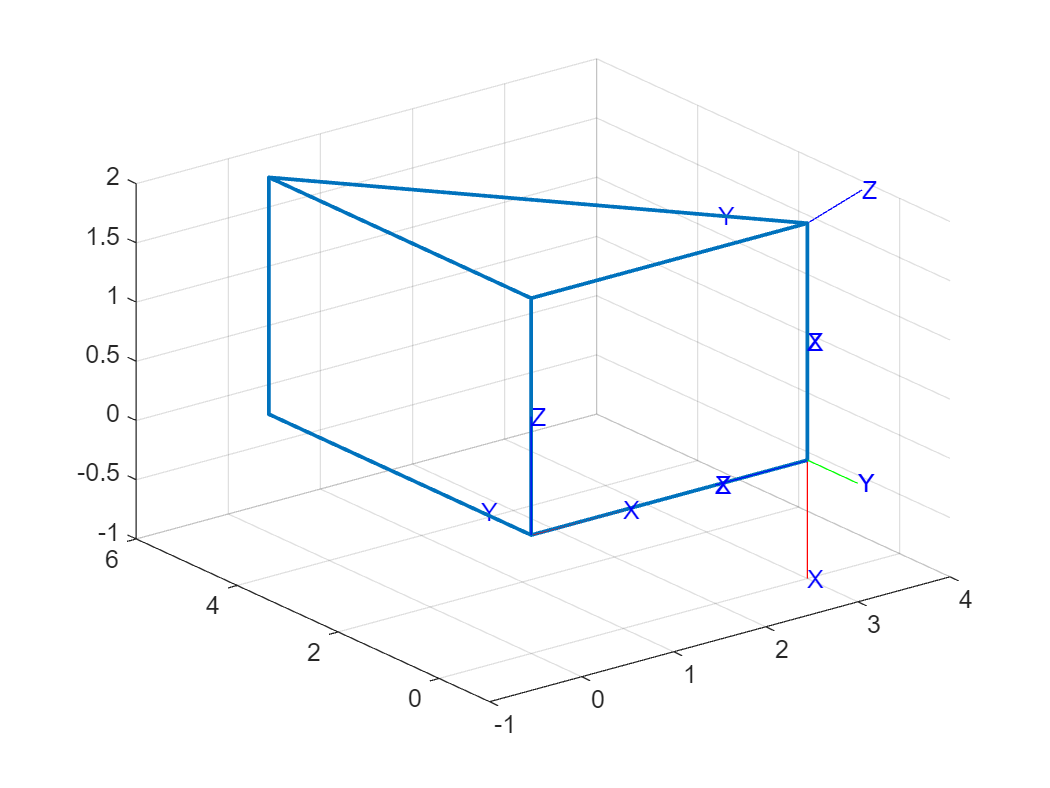


hold off

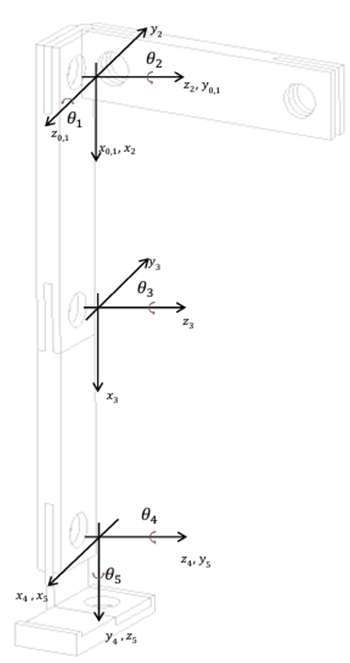

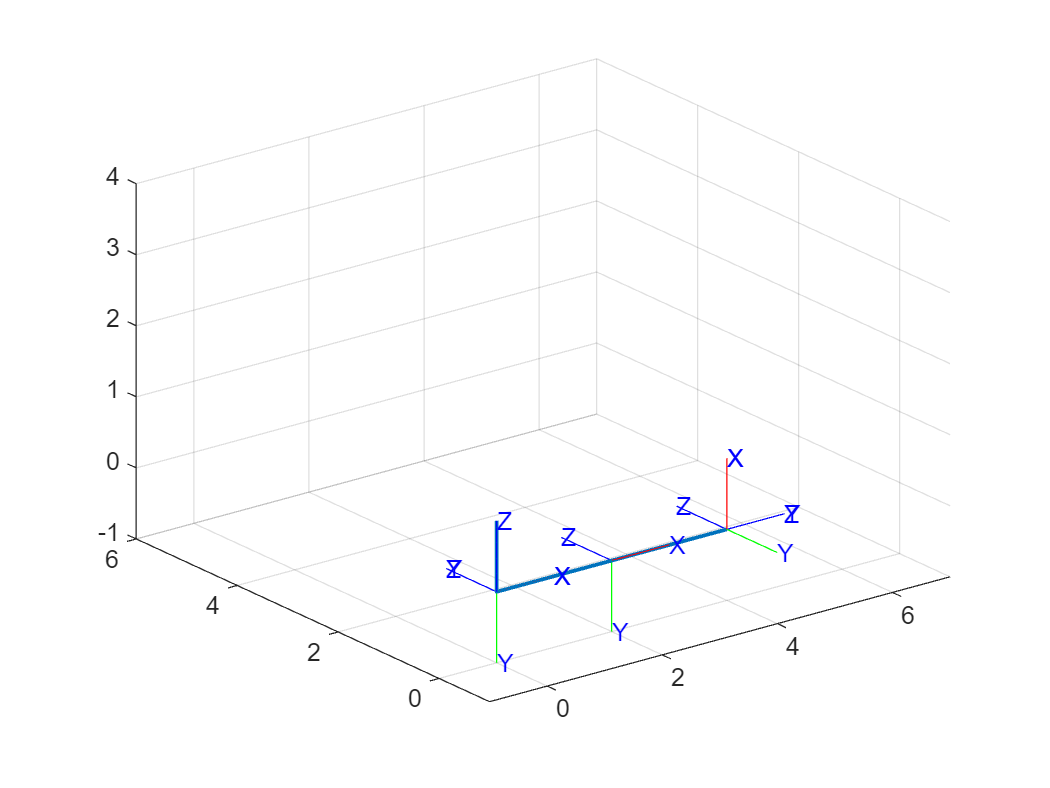

%Calculamos las matrices de transformación homogénea
H0=SE3;
H1=SE3(rotx(-pi/2), [0 0 0]);
H2=SE3(rotx(0), [2 0 0]);
H3=SE3(rotz(-pi/2), [2 0 0]);
H4=SE3(rotx(-pi/2), [0 0 0]);
%H5=SE3(rotz(pi/2), [0 0 1]);
%H6=SE3(rotz(0), [0 0 1]);

H20 = H1*H2;
H30 = H20*H3;
H40 = H30*H4;
%H50 = H40*H5;
%H60 = H50*H6;

%Coordenadas de la estructura de translación y rotación
x=[0 0 2 4 ];
y=[0 0 0 0 ];
z=[1 0 0 0 ];

plot3(x, y, z,'LineWidth', 1.5); axis([-1 7  -1 6 -1 4]); grid on;
hold on;

%Graficamos la trama absoluta o global 
trplot(H0,'rgb','axis', [-1 7 -1 6 -1 2])
% 
% %Realizamos una animación para la siguiente trama
 %pause;
  tranimate(H0, H1,'rgb','axis', [-1 7 -1 6 -1 2])
% %Realizamos una animación para la siguiente trama
 %pause;
 tranimate(H1, H20,'rgb','axis', [-1 7 -1 6 -1 2])
% % %Realizamos una animación para la siguiente trama
 %pause;
  tranimate(H20, H30,'rgb','axis', [-1 77 -1 6 -1 2])
% % %Realizamos una animación para la siuiente trama
 %pause;
  tranimate(H30, H40,'rgb','axis', [-1 7 -1 6 -1 2])

% % %Realizamos una animación para la siguiente trama
 %pause;
  %tranimate(H40, H50,'rgb','axis', [-1 7 -1 6 -1 2])

  %tranimate(H50, H60,'rgb','axis', [-1 7 -1 6 -1 2])

hold off

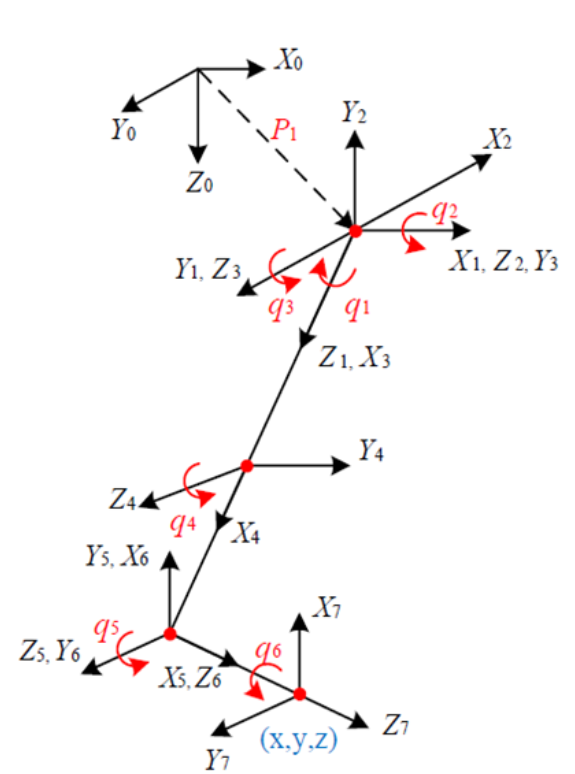

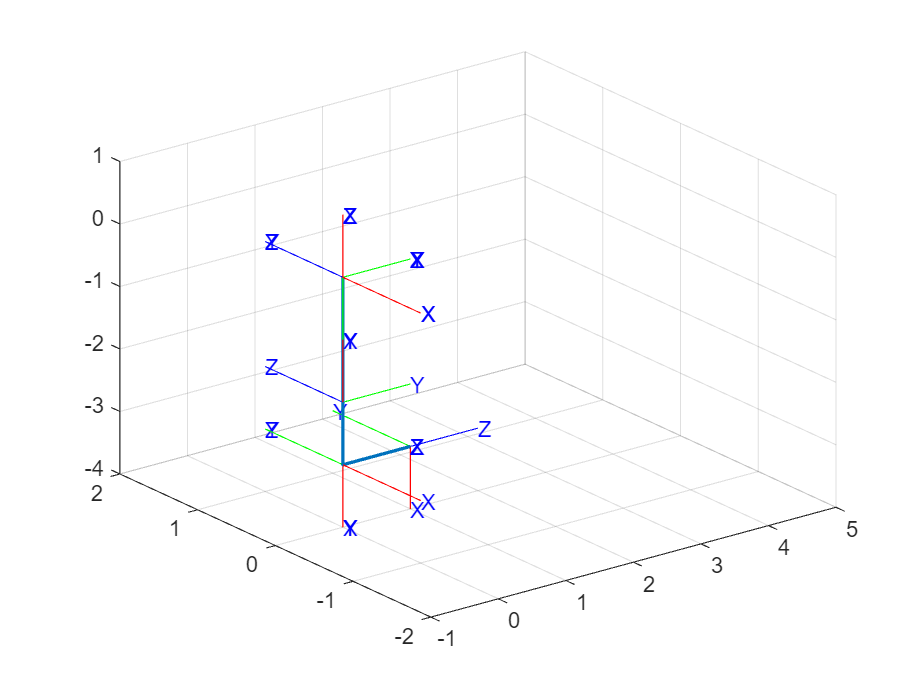

%Calculamos las matrices de transformación homogénea
H0=SE3;
H1=SE3(rotx(-pi/2), [0 0 0]);
H2=SE3(roty(pi/2), [0 0 0]);%2
H3=SE3(rotx(pi/2), [0 0 0]);
H4=SE3(roty(-pi/2), [0 0 0]); %3
H5=SE3(rotz(0), [-2 0 0]);%4
H6=SE3(rotz(pi/2), [-1 0 0]);%5
H7=SE3(roty(pi/2), [0 0 0]);
H8=SE3(rotz(pi/2), [0 0 0]);
H9=SE3(rotz(0), [0 0 1]);

H20 = H1*H2;
H30 = H20*H3;
H40 = H30*H4;
H50 = H40*H5;
H60 = H50*H6;
H70 = H60*H7;
H80 = H70*H8;
H90 = H80*H9;

%Coordenadas de la estructura de translación y rotación
x=[0  0  0  1 ];
y=[0  0  0  0 ];
z=[0 -2 -3 -3 ];

plot3(x, y, z,'LineWidth', 1.5); axis([-1 5  -2 2 -4 1]); grid on;
hold on;

%Graficamos la trama absoluta o global 
trplot(H0,'rgb','axis', [-1 7 -1 6 -1 2])
% 
% %Realizamos una animación para la siguiente trama
 %pause;
  tranimate(H0, H1,'rgb','axis', [-1 7 -1 6 -1 2])
% %Realizamos una animación para la siguiente trama
 %pause;
 tranimate(H1, H20,'rgb','axis', [-1 7 -1 6 -1 2])
% % %Realizamos una animación para la siguiente trama
 %pause;
  tranimate(H20, H30,'rgb','axis', [-1 77 -1 6 -1 2])
% % %Realizamos una animación para la siuiente trama
 %pause;
  tranimate(H30, H40,'rgb','axis', [-1 7 -1 6 -1 2])

% % %Realizamos una animación para la siguiente trama
 %pause;
  tranimate(H40, H50,'rgb','axis', [-1 7 -1 6 -1 2])

  tranimate(H50, H60,'rgb','axis', [-1 7 -1 6 -1 2])

  tranimate(H60, H70,'rgb','axis', [-1 7 -1 6 -1 2])

  tranimate(H70, H80,'rgb','axis', [-1 7 -1 6 -1 2])

  tranimate(H80, H90,'rgb','axis', [-1 7 -1 6 -1 2])

hold off

%Declaración de variables simbólicas
syms th1(t) th2(t) th3(t) th4(t) th5(t) th6(t) t a1 a2 a3

%Configuración del robot, 0 para junta rotacional, 1 para junta prismática
RP=[0 0 0 0 0 0];

%Creamos el vector de coordenadas articulares
Q= [th1, th2, th3, th4, th5, th6];
%disp('Coordenadas generalizadas');
%pretty (Q);

%Creamos el vector de velocidades generalizadas
Qp= diff(Q, t);
%disp('Velocidades generalizadas');
%pretty (Qp);
%Número de grado de libertad del robot
GDL= size(RP,2);
GDL_str= num2str(GDL);

  y_transf= [0 0 1;   %y 90
             0 1 0;
            -1 0 0];

  x_transf= [1  0       0;       %x 150
             0 -0.8660 -0.5000 ;
             0  0.5    -0.8660];  

 Rot2= y_transf*x_transf;
% 
%  rotacion_z= [cos(th2) -sin(th2)  0;
%               sin(th2)  cos(th2)  0;
%                0         0        1];
% 
%  transfor_2= x_transf*rotacion_z;

%%%%%%%%%%%%%%%%%%%
rotx = [1  0  0;
        0  0 -1;
        0  1  0];

rotxN = [1  0  0;
         0  0  1;
         0 -1  0];

roty = [ 0  0  1;
         0  1  0;
        -1  0  0];

rotyN = [ 0  0 -1;
          0  1  0;
          1  0  0];

rotz = [0 -1  0;
        1  0  0;
        0  0  1];

%%%%%%%%%%%%%%%%%%%%%

%% Articulaciones
P = sym(zeros(3, 1, GDL));
R = sym(zeros(3, 3, GDL));

%Articulación 1 
%Posición de la articulación 1 respecto a 0
P(:,:,1)= [0;0;0];
%Matriz de rotación de la junta 1 respecto a 0.... 
Rotz_1 = [cos(th1) -sin(th1)  0;
          sin(th1)  cos(th1)  0;
          0         0         1];


R(:,:,1) = Rotz_1*rotxN*roty;

%Articulación 2
%Posición de la articulación 2 respecto a 1
P(:,:,2)= [0; 0;0];
%Matriz de rotación de la junta 1 respecto a 0.... 
Rotz_2 = [cos(th2) -sin(th2)  0;
          sin(th2)  cos(th2)  0;
          0         0         1];

R(:,:,2) = Rotz_2*rotx*rotyN;

%Articulación 3 
%Posición de la articulación 3 respecto a 2
P(:,:,3)= [0; 0;0];
%Matriz de rotación de la junta 1 respecto a 0.... 
Rotz_3 = [cos(th3) -sin(th3)  0;
          sin(th3)  cos(th3)  0;
          0         0         1];

R(:,:,3) = Rotz_3;

%Articulación 4 
%Posición de la articulación 3 respecto a 2
P(:,:,4)= [a1; 0; 0];
%Matriz de rotación de la junta 1 respecto a 0.... 
R(:,:,4)= [cos(th4) -sin(th4)  0;
           sin(th4)  cos(th4)  0;
           0         0         1];

%Articulación 5 
%Posición de la articulación 3 respecto a 2
P(:,:,5)= [a2; 0; 0];
%Matriz de rotación de la junta 1 respecto a 0.... 
Rotz_5 = [cos(th5) -sin(th5)  0;
          sin(th5)  cos(th5)  0;
          0         0         1];

R(:,:,5) = rotz*Rotz_5;

%Articulación 6 
%Posición de la articulación 3 respecto a 2
P(:,:,6)= [0; 0;0];
%Matriz de rotación de la junta 1 respecto a 0.... 
Rotz_6 = [cos(th6) -sin(th6)  0;
          sin(th6)  cos(th6)  0;
          0         0         1];

R(:,:,6) = roty*rotz*Rotz_6;

%Articulación 7 
%Posición de la articulación 3 respecto a 2
P(:,:,7)= [0; 0; a3];
%Matriz de rotación de la junta 1 respecto a 0.... 
R(:,:,7)= [1  0  0;
           0  1  0;
           0  0  1];



%Creamos un vector de ceros
Vector_Zeros= zeros(1, 3);

%Inicializamos las matrices de transformación Homogénea locales
A(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);
%Inicializamos las matrices de transformación Homogénea globales
T(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);
%Inicializamos las posiciones vistas desde el marco de referencia inercial
PO(:,:,GDL)= P(:,:,GDL); 
%Inicializamos las matrices de rotación vistas desde el marco de referencia inercial
RO(:,:,GDL)= R(:,:,GDL); 


for i = 1:GDL
    i_str= num2str(i);
   %disp(strcat('Matriz de Transformación local A', i_str));
    A(:,:,i)=simplify([R(:,:,i) P(:,:,i); Vector_Zeros 1]);
   %pretty (A(:,:,i));

   %Globales
    try
       T(:,:,i)= T(:,:,i-1)*A(:,:,i);
    catch
       T(:,:,i)= A(:,:,i);
    end
    disp(strcat('Matriz de Transformación global T', i_str));
    T(:,:,i)= simplify(T(:,:,i));
    pretty(T(:,:,i));

    RO(:,:,i)= T(1:3,1:3,i);
    PO(:,:,i)= T(1:3,4,i);
    %pretty(RO(:,:,i));
    %pretty(PO(:,:,i));
end

Matriz de Transformación global T1


/  sin(th1(t)),  0, cos(th1(t)), 0 \
|                                  |
| -cos(th1(t)),  0, sin(th1(t)), 0 |
|                                  |
|       0,      -1,      0,      0 |
|                                  |
\       0,       0,      0,      1 /



Matriz de Transformación global T2


/  sin(th1(t)) sin(th2(t)), cos(th1(t)), -cos(th2(t)) sin(th1(t)), 0 \
|                                                                    |
| -cos(th1(t)) sin(th2(t)), sin(th1(t)),  cos(th1(t)) cos(th2(t)), 0 |
|                                                                    |
|        cos(th2(t)),            0,             sin(th2(t)),       0 |
|                                                                    |
\             0,                 0,                  0,            1 /



Matriz de Transformación global T3


/ cos(th1(t)) sin(th3(t)) + cos(th3(t)) sin(th1(t)) sin(th2(t)), cos(th1(t)) cos(th3(t)) - sin(th1(t)) sin(th2(t)) sin(th3(t)), -cos(th2(t)) sin(th1(t)), 0 \
|                                                                                                                                                           |
| sin(th1(t)) sin(th3(t)) - cos(th1(t)) cos(th3(t)) sin(th2(t)), cos(th3(t)) sin(th1(t)) + cos(th1(t)) sin(th2(t)) sin(th3(t)),  cos(th1(t)) cos(th2(t)), 0 |
|                                                                                                                                                           |
|                    cos(th2(t)) cos(th3(t)),                                       -cos(th2(t)) sin(th3(t)),                          sin(th2(t)),       0 |
|                                                                                                                                                           |
\                               0,                  

Matriz de Transformación global T4


/ cos(th4(t)) #2 + sin(th4(t)) #3, cos(th4(t)) #3 - sin(th4(t)) #2, -cos(th2(t)) sin(th1(t)),            a1 #2           \
|                                                                                                                        |
| cos(th4(t)) #1 + sin(th4(t)) #4, cos(th4(t)) #4 - sin(th4(t)) #1,  cos(th1(t)) cos(th2(t)),            a1 #1           |
|                                                                                                                        |
|       cos(th2(t)) cos(#5),             -cos(th2(t)) sin(#5),             sin(th2(t)),       a1 cos(th2(t)) cos(th3(t)) |
|                                                                                                                        |
\                0,                               0,                            0,                         1             /

where

   #1 == sin(th1(t)) sin(th3(t)) - cos(th1(t)) cos(th3(t)) sin(th2(t))

   #2 == cos(th1(t)) sin(th3(t)) + cos(th3(t)) sin(th1(t)) 

Matriz de Transformación global T5


/ cos(th5(t)) #4 - sin(th5(t)) #3, - cos(th5(t)) #3 - sin(th5(t)) #4, -cos(th2(t)) sin(th1(t)),                      a2 #3 + a1 #6                     \
|                                                                                                                                                      |
| cos(th5(t)) #5 - sin(th5(t)) #2, - cos(th5(t)) #2 - sin(th5(t)) #5,  cos(th1(t)) cos(th2(t)),                      a2 #2 + a1 #8                     |
|                                                                                                                                                      |
|       -cos(th2(t)) sin(#1),             -cos(th2(t)) cos(#1),              sin(th2(t)),       cos(th2(t)) (a1 cos(th3(t)) + a2 cos(th3(t) + th4(t))) |
|                                                                                                                                                      |
\                0,                                0,                             

Matriz de Transformación global T6


/   - cos(th6(t)) #3 - cos(th2(t)) sin(th1(t)) sin(th6(t)),     sin(th6(t)) #3 - cos(th2(t)) cos(th6(t)) sin(th1(t)),   cos(th5(t)) #7 - sin(th5(t)) #6,                     a2 #6 + a1 #10                     \
|                                                                                                                                                                                                               |
|    cos(th1(t)) cos(th2(t)) sin(th6(t)) - cos(th6(t)) #2,      sin(th6(t)) #2 + cos(th1(t)) cos(th2(t)) cos(th6(t)),   cos(th5(t)) #5 - sin(th5(t)) #4,                      a2 #4 + a1 #8                     |
|                                                                                                                                                                                                               |
| sin(th2(t)) sin(th6(t)) - cos(th2(t)) cos(th6(t)) cos(#1), cos(th6(t)) sin(th2(t)) + cos(th2(t)) sin(th6(t)) cos(#1),       -cos(th2(t)) sin(#1),      cos(th2






%Calculamos el jacobiano lineal de forma analítica
Jv_a(:,GDL)=PO(:,:,GDL);
Jw_a(:,GDL)=PO(:,:,GDL);

for k= 1:GDL
    if RP(k)==0 
       %Para las juntas de revolución
        try
            Jv_a(:,k)= cross(RO(:,3,k-1), PO(:,:,GDL)-PO(:,:,k-1));
            Jw_a(:,k)= RO(:,3,k-1);
        catch
            Jv_a(:,k)= cross([0,0,1], PO(:,:,GDL));%Matriz de rotación de 0 con respecto a 0 es la Matriz Identidad, la posición previa tambien será 0
            Jw_a(:,k)=[0,0,1];%Si no hay matriz de rotación previa se obtiene la Matriz identidad
         end
     else
%         %Para las juntas prismáticas
        try
            Jv_a(:,k)= RO(:,3,k-1);
        catch
            Jv_a(:,k)=[0,0,1];
        end
            Jw_a(:,k)=[0,0,0];
     end
 end    

Jv_a= simplify (Jv_a);
Jw_a= simplify (Jw_a);
disp('Jacobiano lineal obtenido de forma analítica');

Jacobiano lineal obtenido de forma analítica


pretty (Jv_a);

/ - a2 (cos(th4(t)) #1 + sin(th4(t)) (cos(th3(t)) sin(th1(t)) + cos(th1(t)) sin(th2(t)) sin(th3(t)))) - a1 #1,  cos(th2(t)) sin(th1(t)) #5, #3, #3,    #10 - #9 - #8 - #7,    0 \
|                                                                                                                                                                               |
|  a2 (cos(th4(t)) #2 + sin(th4(t)) (cos(th1(t)) cos(th3(t)) - sin(th1(t)) sin(th2(t)) sin(th3(t)))) + a1 #2,  -cos(th1(t)) cos(th2(t)) #5, #4, #4,   #13 - #14 + #12 + #11,  0 |
|                                                                                                                                                                               |
\                                                      0,                                                            -sin(th2(t)) #5,       #6, #6, -a2 cos(th2(t)) sin(#15), 0 /

where

   #1 == sin(th1(t)) sin(th3(t)) - cos(th1(t)) cos(th3(t)) sin(th2(t))

   #2 == cos(th1(t)) sin(th3(t

disp('Jacobiano ángular obtenido de forma analítica');

Jacobiano ángular obtenido de forma analítica


pretty (Jw_a);

/ 0, cos(th1(t)),      #1,          #1,          #1,          #1     \
|                                                                    |
| 0, sin(th1(t)),      #2,          #2,          #2,          #2     |
|                                                                    |
\ 1,      0,      sin(th2(t)), sin(th2(t)), sin(th2(t)), sin(th2(t)) /

where

   #1 == -cos(th2(t)) sin(th1(t))

   #2 == cos(th1(t)) cos(th2(t))






disp('Velocidad lineal obtenida mediante el Jacobiano lineal');

Velocidad lineal obtenida mediante el Jacobiano lineal


V=simplify (Jv_a*Qp');
pretty(V);

/ #6 cos(th2(t)) sin(th1(t)) #10 - #3 (#14 - #15 + #13 + #12) - #5 #8 - #4 #8 - #7 (a2 (cos(th4(t)) #1 + sin(th4(t)) (cos(th3(t)) sin(th1(t)) + cos(th1(t)) sin(th2(t)) sin(th3(t)))) + a1 #1) \
|                                                                                                                                                                                              |
| #7 (a2 (cos(th4(t)) #2 + sin(th4(t)) (cos(th1(t)) cos(th3(t)) - sin(th1(t)) sin(th2(t)) sin(th3(t)))) + a1 #2) + #3 (#18 - #19 + #17 + #16) + #5 #9 + #4 #9 - #6 cos(th1(t)) cos(th2(t)) #10 |
|                                                                                                                                                                                              |
\                                                  - #6 sin(th2(t)) #10 - #5 cos(th2(t)) #11 - #4 cos(th2(t)) #11 - a2 #3 cos(th2(t)) sin(#20)                                                 /

where

   #1 == sin(th1(t)) sin(th

disp('Velocidad angular obtenida mediante el Jacobiano angular');

Velocidad angular obtenida mediante el Jacobiano angular


W=simplify (Jw_a*Qp');
    pretty(W);

/ #5 cos(th1(t)) - #4 cos(th2(t)) sin(th1(t)) - #3 cos(th2(t)) sin(th1(t)) - #2 cos(th2(t)) sin(th1(t)) - #1 cos(th2(t)) sin(th1(t)) \
|                                                                                                                                    |
| #5 sin(th1(t)) + #4 cos(th1(t)) cos(th2(t)) + #3 cos(th1(t)) cos(th2(t)) + #2 cos(th1(t)) cos(th2(t)) + #1 cos(th1(t)) cos(th2(t)) |
|                                                                                                                                    |
|                            _________                                                                                               |
|                             d                                                                                                      |
|                            -- th1(t) + #4 sin(th2(t)) + #3 sin(th2(t)) + #2 sin(th2(t)) + #1 sin(th2(t))                           |
\                            dt                        